***Integrantes***:

- Naysla tatiana torres Cortes

# MÉTODO EULER

**Ejercicio 1**

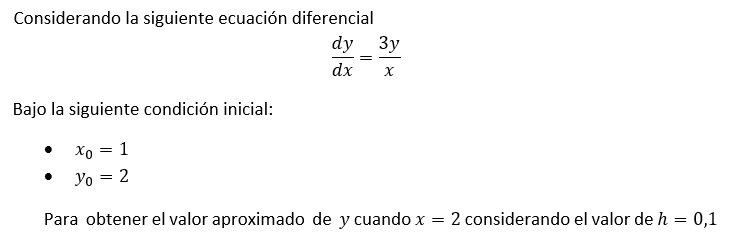

%datos iniciales
x0=1;
y0=1;
x=2;
h=0,1;

h = 0

n=11; % se toma como 11 para que en ese punto el valor de x sea 2 y se 
%obtenga la respuesta requerida
%Paso 1 determinar la tabla
strcat('x0=',num2str(x0),' y0=', num2str(y0),' x=', num2str(x),' y=?')

ans = 'x0=1 y0=1 x=2 y=?'

%Paso 2 Determinar el valor de h, nos lo dan desde el inicio, no se hace
%uso de la fórmula
h=0.1

h = 0.1000

%Paso 3 Identificar por cada paso n x sub i
strcat('_n_','_xi_')

ans = '_n__xi_'

 xi =x0;
for i = 1:n   
    strcat(' ',num2str(i),' _ _', num2str(xi))
    xi=xi+h;
end

ans = '1 _ _1'

ans = '2 _ _1.1'

ans = '3 _ _1.2'

ans = '4 _ _1.3'

ans = '5 _ _1.4'

ans = '6 _ _1.5'

ans = '7 _ _1.6'

ans = '8 _ _1.7'

ans = '9 _ _1.8'

ans = '10 _ _1.9'

ans = '11 _ _2'

%Paso 4 identificar yi , y' por cada n
yi =y0

yi = 1

xi =x0

xi = 1

x=xi

x = 1

f=EvaluarFuncion(xi,yi)

f = 3

strcat('_n_ xi _ yi _ yPri_')

ans = '_n_ xi _ yi _ yPri_'

for j = 1:n 
    strcat(' ',num2str(j),' _ ', num2str(xi),' _ ', num2str(yi),' _ ',num2str(f))
    if (j~=11)
        xi=xi+h;
        yi = Valoryi(yi, f, h);
        f=EvaluarFuncion(xi,yi) ;
    end   
    
end

ans = '1 _1 _1 _3'

ans = '2 _1.1 _1.3 _3.5455'

ans = '3 _1.2 _1.6545 _4.1364'

ans = '4 _1.3 _2.0682 _4.7727'

ans = '5 _1.4 _2.5455 _5.4545'

ans = '6 _1.5 _3.0909 _6.1818'

ans = '7 _1.6 _3.7091 _6.9545'

ans = '8 _1.7 _4.4045 _7.7727'

ans = '9 _1.8 _5.1818 _8.6364'

ans = '10 _1.9 _6.0455 _9.5455'

ans = '11 _2 _7 _10.5'

 %Respuesta
 strcat('La respuesta es:')

ans = 'La respuesta es:'

 strcat('cuando X es_', num2str(xi),' El Valor aproximado de y es_ ', num2str(yi))

ans = 'cuando X es_2 El Valor aproximado de y es_7'

***FUNCIONES***  

function f = EvaluarFuncion(x,y)    
    f = (3*y)/x;
end
function [y]=Valoryi(yi, f, h) 
    y = yi+ (f*h);
end

